## Question 1

clear
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




m = 0.712;
k = 3.28e3;
d = 0.17768;
L = 0.8;
R = 14.8;
k_i = 14.9;
k_s = 139.4;

G_ol = (1000 * k_i) / (L*m*s^3 + (L*d + R*m)*s^2 + (L*k-L*k_s+R*d+k_i^2)*s + R*k-R*k_s)

G_ol =
 
                    14900
  ------------------------------------------
  0.5696 s^3 + 10.68 s^2 + 2737 s + 4.648e04
 
Continuous-time transfer function.



Calculate system poles, zeros, gain, type, damping, undamped frequency etc, for the three working points��

fprintf("Poles");

Poles

poles = pole(G_ol); poles

poles =   -0.8333 +69.1098i
  -0.8333 -69.1098i
 -17.0829 + 0.0000i



fprintf("gain må bare være 14900")

gain må bare være 14900


fprintf("Typen af system er type 3, da det er et tredje ordens system.")

Typen af system er type 3, da det er et tredje ordens system.


fprintf("Damping Ratio, undamped (natural) frequency  og Time Constant findes ved den smarte smarte funktion damp()")

Damping Ratio, undamped (natural) frequency  og Time Constant findes ved den smarte smarte funktion damp()

damp(G_ol)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.71e+01                 1.00e+00       1.71e+01         5.85e-02    
 -8.33e-01 + 6.91e+01i     1.21e-02       6.91e+01         1.20e+00    
 -8.33e-01 - 6.91e+01i     1.21e-02       6.91e+01         1.20e+00    


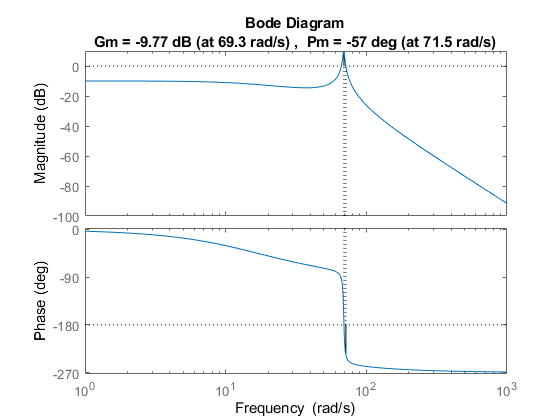


margin(G_ol)

Table 2

fprintf("Table 2 ----------------------------------------------------------")

Table 2 ----------------------------------------------------------

clear
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




m = 0.712;
k = 3.28e3;
d = 0.17768;
L = 0.8;
R = 14.8;
k_i = 44.8;
k_s = 1254;

G_ol = (1000 * k_i) / (L*m*s^3 + (L*d + R*m)*s^2 + (L*k-L*k_s+R*d+k_i^2)*s + R*k-R*k_s)

G_ol =
 
                    44800
  ------------------------------------------
  0.5696 s^3 + 10.68 s^2 + 3630 s + 2.998e04
 
Continuous-time transfer function.



Calculate system poles, zeros, gain, type, damping, undamped frequency etc, for the three working points��

fprintf("Poles");

Poles

poles = pole(G_ol); poles

poles =   -5.1881 +79.1196i
  -5.1881 -79.1196i
  -8.3733 + 0.0000i



fprintf("gain må bare være 44800")

gain må bare være 44800


fprintf("Typen af system er type 3, da det er et tredje ordens system.")

Typen af system er type 3, da det er et tredje ordens system.


fprintf("Damping Ratio, undamped (natural) frequency  og Time Constant findes ved den smarte smarte funktion damp()")

Damping Ratio, undamped (natural) frequency  og Time Constant findes ved den smarte smarte funktion damp()

damp(G_ol)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -8.37e+00                 1.00e+00       8.37e+00         1.19e-01    
 -5.19e+00 + 7.91e+01i     6.54e-02       7.93e+01         1.93e-01    
 -5.19e+00 - 7.91e+01i     6.54e-02       7.93e+01         1.93e-01    


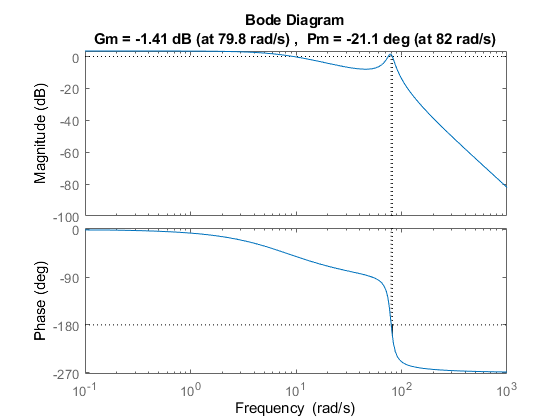


margin(G_ol)

Table 3

fprintf("Table 3 ----------------------------------------------------------")

Table 3 ----------------------------------------------------------

clear
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




m = 0.712;
k = 3.28e3;
d = 0.17768;
L = 0.8;
R = 14.8;
k_i = 74.7;
k_s = 3484;

G_ol = (1000 * k_i) / (L*m*s^3 + (L*d + R*m)*s^2 + (L*k-L*k_s+R*d+k_i^2)*s + R*k-R*k_s)

G_ol =
 
                  74700
  --------------------------------------
  0.5696 s^3 + 10.68 s^2 + 5420 s - 3019
 
Continuous-time transfer function.



Calculate system poles, zeros, gain, type, damping, undamped frequency etc, for the three working points��

fprintf("Poles");

Poles

poles = pole(G_ol); poles

poles =   -9.6530 +97.1194i
  -9.6530 -97.1194i
   0.5565 + 0.0000i



fprintf("gain må bare være 74700")

gain må bare være 74700


fprintf("Typen af system er type 3, da det er et tredje ordens system.")

Typen af system er type 3, da det er et tredje ordens system.


fprintf("Damping Ratio, undamped (natural) frequency  og Time Constant findes ved den smarte smarte funktion damp()")

Damping Ratio, undamped (natural) frequency  og Time Constant findes ved den smarte smarte funktion damp()

damp(G_ol)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  5.56e-01                -1.00e+00       5.56e-01        -1.80e+00    
 -9.65e+00 + 9.71e+01i     9.89e-02       9.76e+01         1.04e-01    
 -9.65e+00 - 9.71e+01i     9.89e-02       9.76e+01         1.04e-01    


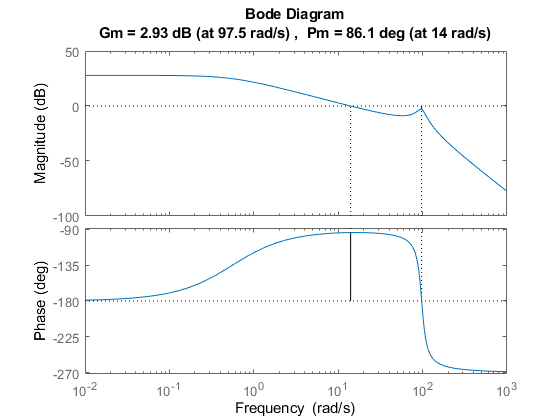


margin(G_ol)

## Question 2

**Formulate realistic requirements:**

It is seen, that the system oscillates a great deal. This correlates with an overshoot, that we would like to eliminate. In the real world, a big overshoot could mean that the mass and the magnets would collide. The main requirement of the controller could be to stop the oscilliations and decrease the overshoot.

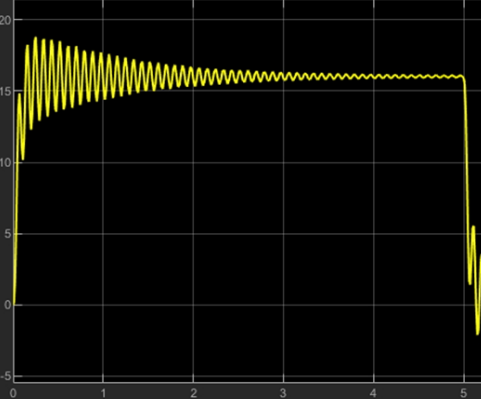

## Question 3

**Diffiqulty of performance:**

It is seen from the Open Loop System, that the phase change is very steep, resulting in that the controller must be very "attack*"* the frequency domain with very high accuracy. Also, it is seen that the magnitude is >0dB where the phase is -180 degrees, resulting in an unstable system *(ref side 150-151)*.

P-controller: Seeing that we are already dealing with an unstable system, we would have to implement a low KP to reduce the gain, resulting in lower accuracy slower reaction speed.

PI-controller: In the time domain, the PI controller will reduce the steady state error compared to the P-controller, however the cost can be a slower reaction speed. The open loop frequency domain is decreased with between 90 and 0 degrees between omega = 0 and the corner/cut/break-frequency, which we don't need.

P-lead-controller: For the open-loop frequency response, we see an increase in the band between the zero and the pole, while also seeing an increase in the magnitude in the same band. In the time domain, we see a rapid reaction, which can result in overshoot. *Dette kunne være et problem, da det ville forstærke vores oscillationer?*

PI-Lead-controller: *Det ser meget fornuftigt ud, er det ikke bare sådan en man skal lave? Man kan umiddelbart få et løft i fasen, men skal måske passe lidt på med ikke at få magnituden for meget op. ref side 216.*

*Spørgsmål: Kan det passe, at man når man vil kigge på open-loop mest tjekker frekvenssomænet, og når man kigger på closed loop kigger mest på tidsdomænet? I så fald, for at svare på spørgsmålet om hvordan closed loop performance bliver påvirket, skal svaret baseres hovedsagligt på et step respons.*